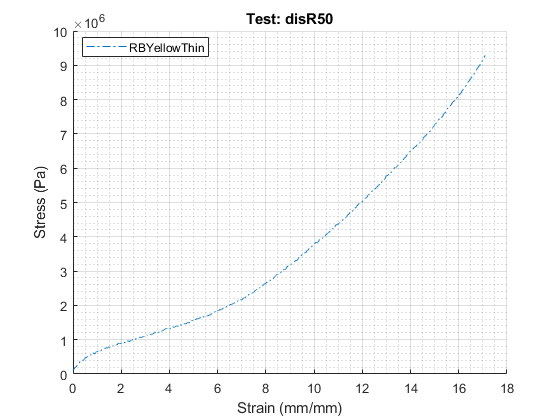

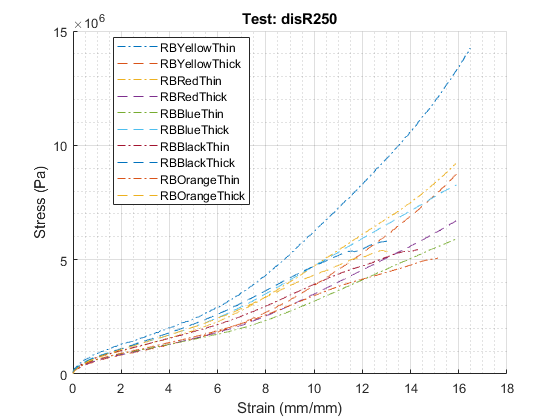

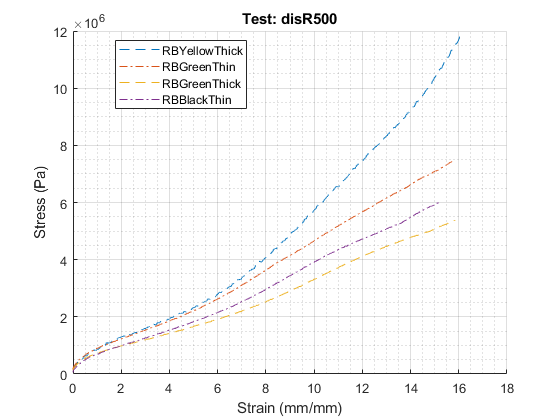

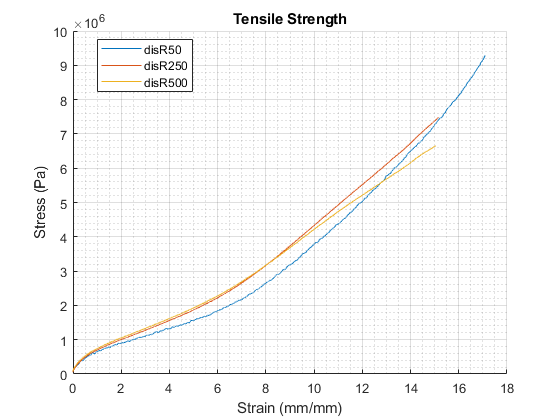

clear all
close all
%Simple test to verify that the stress data for rubber bands is correct
load('TrainingSetProcStressV4.mat');
N = length( fieldnames(PmatData) );
fields.N = fieldnames(PmatData);

for i=7
    M = length( fieldnames(PmatData. ( fields.N{i} ) ) );
    fields.M = fieldnames(PmatData.( fields.N{i} ) );
    for j=1:M
        P = length( PmatData. ( fields.N{i} ).(fields.M{j}));
        figure
        grid on
        grid minor
        hold on
        for k=1:P
            x = PmatData.(fields.N{i}).(fields.M{j})(k).pstrain;
            y = PmatData.(fields.N{i}).(fields.M{j})(k).sstress;
            if isempty(...
                    strfind(...
                    PmatData.(fields.N{i}).(fields.M{j})(k).name,'Thin'))
                %Thick
                lineStyle = '--';
            else
                %Thin
                lineStyle = '-.';
            end
            plot(x,y,'LineStyle',lineStyle,...
                'DisplayName',PmatData.(fields.N{i}).(fields.M{j})(k).name);
            xlim([0 18]);
        end
        title(strcat("Test: ",fields.M{j}));
        legend('Location','Best');
        xlabel('Strain (mm/mm)');
        ylabel('Stress (Pa)');
    end
end

for i=7
    figure
    grid on
    grid minor
    hold on    
    for j=1:M
        P = length( PmatData. ( fields.N{i} ).(fields.M{j}));        
        if P>1
            x = PmatData.(fields.N{i}).(fields.M{j})(1).mpstrain;
            y = PmatData.(fields.N{i}).(fields.M{j})(1).msstress;
        else
            x = PmatData.(fields.N{i}).(fields.M{j})(1).pstrain;
            y = PmatData.(fields.N{i}).(fields.M{j})(1).sstress;
        end
        plot(x,y,'DisplayName',fields.M{j} );        
    end
    xlim([0 18]);
    title('Tensile Strength');
    legend('Location','Best');
    xlabel('Strain (mm/mm)');
    ylabel('Stress (Pa)');
end